# Частотная модуляция 

# Основы

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Введение

Одним из наиболее распространенных видов аналоговой модуляции является частотная модуляция. Ее преимущество относительно амплитудной модуляции состоит в лучшей помехоустойчивости. Однако, это перимущество достигается за счет большей полосы сигнала и усложнения приемного устройства. При частотной модуляции мгновенная частота несущего сигнала изменяется в соответвии с амплитудой информационного сообщения. 

В общем виде после модуляции передаваемый сигнал можно представить в виде:

$s\left(t\right)=A\left(t\right)\cdot \cos \left(\theta \left(t\right)\right)$,              (1)

где $A\left(t\right)$ - амплитуда сигнала, $\theta \left(t\right)$ - фаза сигнала.

В случае амплитудной модуляции амплитуда $A\left(t\right)$ изменяется пропорционально информационному сообщению $m\left(t\right)$, а фаза изменяется линейно, как $\theta \left(t\right)=\omega_с t$, где $\omega_с$ - частота несущей.

При частотной модуляции амплитуда сигнала является константой $A\left(t\right)=A_с$, а пропорционально информационному сообщению $m\left(t\right)$ изменяется мгновенная частота несущей, которая выражается через фазу $\theta \left(t\right)$ с помощью производной:

$\frac{d}{\textrm{dt}}\theta \left(t\right)=\omega \left(t\right)=2\pi \cdot f\left(t\right)$.

Мгновенная частота в герцах $f\left(t\right)$ обычно представляется как сумма частоты несущей $f_с$ и информационного сообщения $m\left(t\right)$, умноженного на константу $K_f$, которая называется чувствительностью модулятора (frequency sensetivity):

 $f\left(t\right)=f_с +K_f \cdot m\left(t\right)$.

Выразим фазу сигнала через его мгновенную частоту с помощью интегрирования:

$\theta \left(t\right)=\int_{-\infty }^t 2\pi \cdot f\left(t\right)\cdot \textrm{dt}=2\pi \cdot \int_{-\infty }^t \left\lbrack f_с +K_f \cdot m\left(t\right)\right\rbrack \cdot \textrm{dt}=2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(t\right)\cdot \textrm{dt}+\theta_0 ,$    (2)

где $\theta_0$ - начальная фаза, которую в дальнейшем примем равной нулю.

Из уравнения (2) можно увидеть, что фаза сигнала изменяется пропорционально интегралу от информационного сииобщения. Подставляя уравнение (2) в формулу (1), получим общее выражение для сигнала с частотной модуляцией:

 
$$s\left(t\right)=A\left(t\right)\cdot \cos \left(\theta \left(t\right)\right)=A_с \cdot \cos \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)\;\;\;\;\;\;\;\;\left(3\right),$$


где $A_с$ - амплитуда несущей, $f_с$ - частота несущей, $K_f$ - чувствительность модулятора.

Схема частотного модулятора представлена ниже:

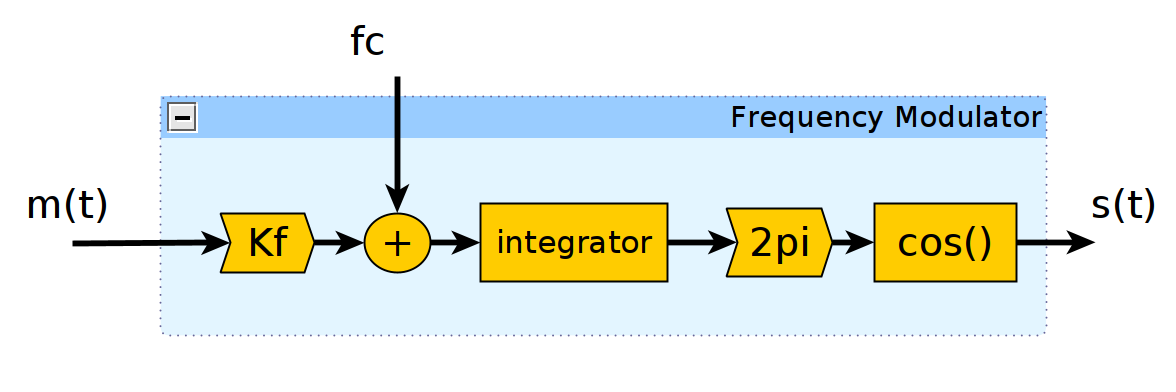

Введем еще два важных понятия. Мгновенная частота сигнала в герцах равна:

  
$$f\left(t\right)=f_с +K_f \cdot m\left(t\right)\ldotp$$


Максимальное отклонение мгновенной частоты от частоты несущей называют девиацией (frequency deviation):


$$\Delta f=\max \left|f\left(t\right)-f_с \right|=\max \left|f_с +K_f \cdot m\left(t\right)-f_с \right|=\max \left|K_f \cdot m\left(t\right)\right|=K_f \cdot \max \left|m\left(t\right)\right|\ldotp$$


Таким образом, девиация зависит от чувствительности модулятора и максимального значения информационного сообщения.

Индексом модуляции (modulation index) называют отношение девиации частоты к максимальной частоте в спектре информацонного сообщения:


$$\beta =\frac{\Delta f}{f_m }=\frac{K_f \cdot \max \left|m\left(t\right)\right|}{f_m },$$


где $f_m$ - максимальная частота в спектре информационного сообщения.

Как будет показано в дальнейшем, девиация определяется полосу модулированного сигнала. Чем больше девиация, тем шире полоса. Индекс модуляции - это просто девиация, нормированная на полосу сообщения. Индексом модуляции удобно пользоваться для определения является ли модуляция узкополосной или широкополосной.

### 2. Однотональная модуляция

Продолжим рассмотрение частотной модуляции с наиболее простого случая модуляции однотонольным сообщением. Информационное сообщение представляет из себя гармонический сигнал вида: 

$m\left(t\right)=A_m \cos \left(2\pi f_m t\right)$,

где $A_m$ - амплитуда тона, $f_m$ - частота в герцах. 

Максимальное значение однотонального сообщения равно его амплитуде $A_m$. Отсюда получаем, что девиация $\Delta f$равна произведения $K_f A_m$. Далее, так как спектр сообщения состоит всего из одной гармоники, максмальная частота в спектре равна частоте этой гармоники $f_m$. Таким образом, в случае однотональной модуляции индекс модуляции задается как

 
$$\beta =\frac{\Delta f}{f_m }=\frac{K_f A_m }{f_m }\ldotp$$


Ниже представлен скрипт, реализующий однотональную частотную модуляцию. Модуляция несущей выполняется с помощью уравнения (3). Сначала рассчитывается мгновенная частота несущей $f\left(t\right)=f_с +K_f \cdot m\left(t\right)$. Далее, она интегрируется с помощью функции cumsum(), и получается фаза сигнала. Эта фаза используется для формирования передаваемого сигнала FmSignal. Чувствительность модулятора задается с помощью индекса модуляции в виде:

$K_f =\frac{\beta \cdot f_m }{A_m }$.

Изменяя переменную ModIndex, задающую индекс модуляции $\beta$, можно увидеть, ее влияние на временную диаграмму сигнала. 

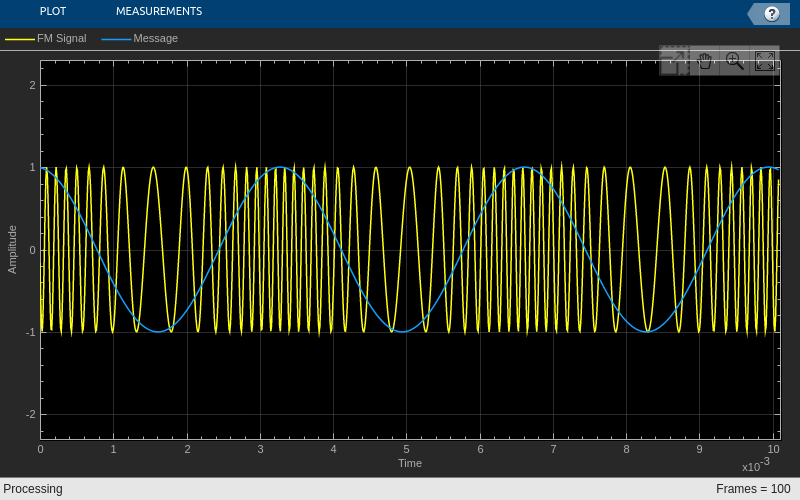

clc; clear; close all;

FrameSize = 1011;                % размер обрабатываемой за один раз пачки данных
Fs = 100e3;                      % частота дискретизации (Hz)
Fc = 5e3;                        % частота несущей (Hz)
Am = 1;                          % амплитуда тонального сообщения
Fm = 300;                        % частота тонального сообщения (Hz)
ModIndex = 10;   % индекс модуляции

% вычисление чувствительности модулятора
Kf = ModIndex * Fm / Am;

% генератор однотонального сигнала
% частота тона: 5 kHz
Message = dsp.SineWave(...
    'SampleRate',Fs,...
    'SamplesPerFrame',FrameSize,...
    'Frequency', Fm,...
    'Amplitude', Am ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType', 'Line', ...
    'YLimits', [-2.3, 2.3], ...
    'SampleIncrement', 1/Fs, ...
    'XLabel', 'Time', ...
    'YLabel', 'Amplitude', ...
    'ChannelNames', {'FM Signal', 'Message'} ...
    );

% начальная фаза интегратора
InitPhase = 0;

% запуск симуляции
for i = 1:100
    % формирование тонального сигнала
    MessageData = Message();

    % вычисление мгновенной частоты (Hz)
    freq = Fc + Kf * MessageData;
    
    % вычисление фазы в радианах c помощью интегрирования
    phase = InitPhase + 2*pi/Fs * cumsum(freq);
    
    % обновление начальной фазы интегратора
    InitPhase = phase(end);
    
    % формирование модулированного сигнала
    FmSignal = cos(phase);
    
    % вывод результатов на график
    Plotter([FmSignal, MessageData])
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

На временной диаграмме можно увидеть однотональное сообщение (синий цвет) и частотно-модулированный сигнал (желтый цвет). Частота сигнала изменяется пропорционально амплитуде информационного сообщения, чем больше значение сообщения, тем больше частота и наоборот. Также можно заметить, что при увеличении индекса модуляции изменения частоты несущей становятся более выраженными.

Теперь рассмотрим, как выглядит спектр сигнала при однотональной частотной модуляции. В отличие от амплитудной модуляции, которая является линейной, и при которой спектр информационного сообщения просто смещается по частоте, спектр сигнал при частотной модуляции устроен более сложным образом. Он существенным образом зависит от индекса модуляции и может содержать спектральные компоненты, которых не было в исходном сообщении. 

Скрипт, позволяющий увидеть спектр сигнала при однотональной частотной модуляции, представлен ниже. Изменяя переменную ModIndex, задающую индекс модуляции $\beta$, можно увидеть, ее влияние на спектр сигнала. Зависимость спектра от индекса модулции для однотонального случая будет более подробно раскрыта в LiveScripts по узкополосной и широкополосной частотной модуляции.

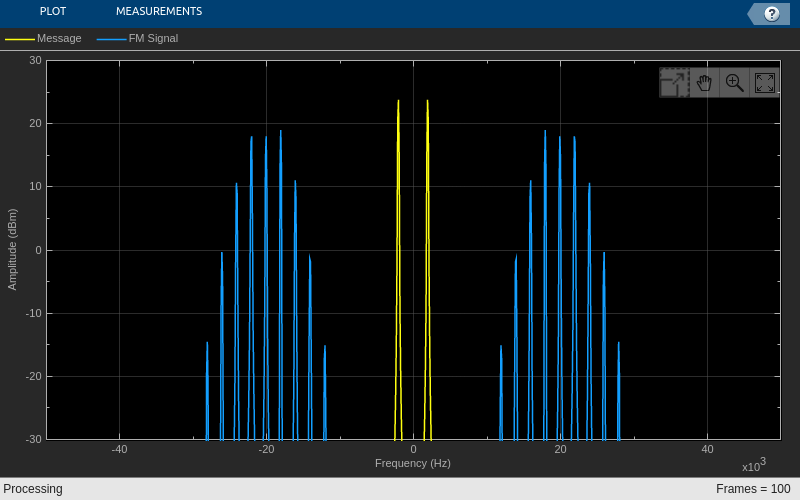

clc; clear; close all;

FrameSize = 1011;                % размер обрабатываемой за один раз пачки данных
Fs = 100e3;                      % частота дискретизации (Hz)
Fc = 20e3;                       % частота несущей (Hz)
Am = 1;                          % амплитуда тонального сообщения
Fm = 2e3;                        % частота тонального сообщения (Hz)
ModIndex = 1.5;   % индекс модуляции

% вычисление чувствительности модулятора
Kf = ModIndex * Fm / Am;

% генератор однотонального сигнала
% частота тона: 5 kHz
Message = dsp.SineWave(...
    'SampleRate',Fs,...
    'SamplesPerFrame',FrameSize,...
    'Frequency', Fm,...
    'Amplitude', Am ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm', ...
    'FrequencyRange', 'centered', ...
    'SampleRate', Fs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -Fs/2, ...
    'YLimits', [-30, 30], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'FM Signal'}, ...
    'SampleIncrement', Fs/FrameSize ...
    );

% начальная фаза интегратора
InitPhase = 0;

% запуск симуляции
for i = 1:100
    % формирование тонального сигнала
    MessageData = Message();

    % вычисление мгновенной частоты (Hz)
    freq = Fc + Kf * MessageData;
    
    % вычисление фазы в радианах c помощью интегрирования
    phase = InitPhase + 2*pi/Fs * cumsum(freq);
    
    % обновление начальной фазы интегратора
    InitPhase = phase(end);
    
    % формирование модулированного сигнала
    FmSignal = cos(phase);
    
    % вычисление спектров
    Spectrums = SpecEstimator([MessageData, FmSignal]);
    
    % вывод результатов на график
    Plotter(Spectrums)
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

На сперктрограмме выше спектр информационного тонального сообщения предствален желтым цевтом и состоит из двух дельта-функций на частотах $f_m$ и $-f_m$. Спектр модулированного сигнала обозначен синим цветом. При малом значении индекса модуляции $\beta$ спектр содержит три тона: несущая и две боковых компоненты. Это очень напоминает спектр АМ-сигнал при однотональной модуляции. Однако, при увиличении индекса модуляции $\beta$ в спектре появляется множетсво гармоник и его ширина существенно возрастает. Таким образом, как уже упоминалось, спектр ЧМ-сигнала имеет более сложную структуру, по сравнению с АМ-сигналом.

### 3. Модуляция несколькими тонами

Теперь рассмотрим более сложных случай, когда информационный сигнал представляет из себя сумму гармонических сигналов:

$m\left(t\right)=\sum_{i=1}^N A_i \cos \left(2\pi f_i t\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(4\right)$,

где $A_i$ - амплитада i-ой гармоники, $f_i$ - частота i-ой гармоники, $N$ - число гармоник.

Максимальное значение, которое может принимать информационное сообщение равно сумме амплитуд отдельных гармоник, то есть 


$$\max \left|m\left(t\right)\right|=\sum_{i=1}^N A_i \ldotp$$
 

Отсюда получаем, что девиация $\Delta f$равна произведения $K_f \cdot \sum_{i=1}^N A_i$. Далее, максмальная частота в спектре сообщения равна частоте самой высокой гармоники. Если считать, что в (4) в сумме гармоники располагаются по возрастанию частоты, то максимальная частота в спектре сообщения равна $f_m =f_N$. Значит, при модуляции несколькми тонами индекс модуляции можно записать в виде:

 
$$\beta =\frac{\Delta f}{f_m }=\frac{K_f \cdot \sum_{i=1}^N A_i }{f_N },$$


где $N$- число гармоник. 

Тогда чувствиельность модулятора можно представить в виде:

 
$$K_f =\frac{\beta \cdot f_N }{\sum_{i=1}^N A_i }\ldotp$$


В случае, если в модуляции учавствуют три тона, график временная диаграмма сигнала будет иметь вид:

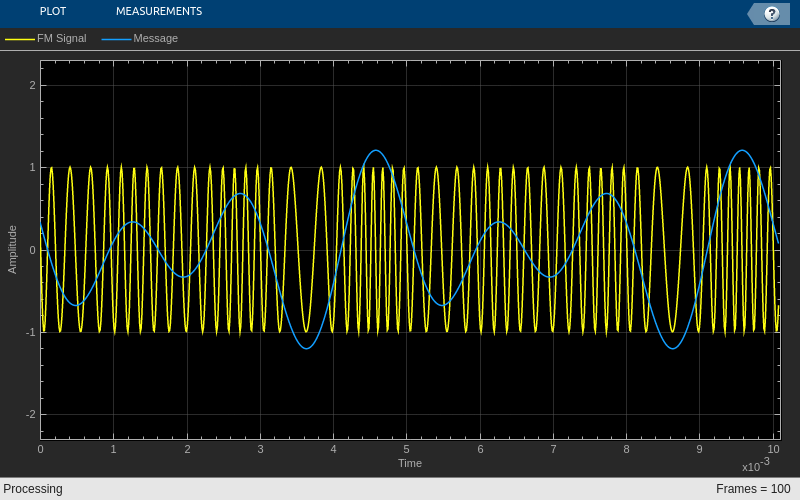

clc; clear; close all;

FrameSize = 1011;                % размер обрабатываемой за один раз пачки данных
Fs = 100e3;                      % частота дискретизации (Hz)
Fc = 5e3;                        % частота несущей (Hz)
Am = [0.1 0.5 0.7];              % амплитуды тональнов сообщения
Fm = [200 400 600];              % частоты тональнов сообщения (Hz)
ModIndex = 5;   % индекс модуляции

% вычисление чувствительности модулятора
Kf = ModIndex * Fm(end) / sum(Am);

% генератор сообщения из трех тонов
Message = dsp.SineWave(...
    'SampleRate', Fs, ...
    'SamplesPerFrame', FrameSize, ...
    'Frequency', Fm, ...
    'Amplitude', Am ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType', 'Line', ...
    'YLimits', [-2.3, 2.3], ...
    'SampleIncrement', 1/Fs, ...
    'XLabel', 'Time', ...
    'YLabel', 'Amplitude', ...
    'ChannelNames', {'FM Signal', 'Message'} ...
    );

% начальная фаза интегратора
InitPhase = 0;

% запуск симуляции
for i = 1:100
    % формирование сообщения из нескольких тонов
    MessageData = Message();
    MessageData = MessageData(:,1) + MessageData(:,2) + MessageData(:,3);

    % вычисление мгновенной частоты (Hz)
    freq = Fc + Kf * MessageData;
    
    % вычисление фазы в радианах c помощью интегрирования
    phase = InitPhase + 2*pi/Fs * cumsum(freq);
    
    % обновление начальной фазы интегратора
    InitPhase = phase(end);
    
    % формирование модулированного сигнала
    FmSignal = cos(phase);
    
    % вывод результатов на график
    Plotter([FmSignal, MessageData])
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

Как и для однотональной модуляции, можно увидеть, что частота несущей пропорциональна амплитуде информационного сообщения. Причем, при увеличении индекса модуляции эта зависимость выражается более ярко.

Рассмотрим спектр ЧМ-сигнала при модуляции несколькими тонами. Скрипт, позволяющий увидеть спектр сигнала, представлен ниже. Изменяя переменную ModIndex, задающую индекс модуляции $\beta$, можно увидеть, ее влияние на спектр. 

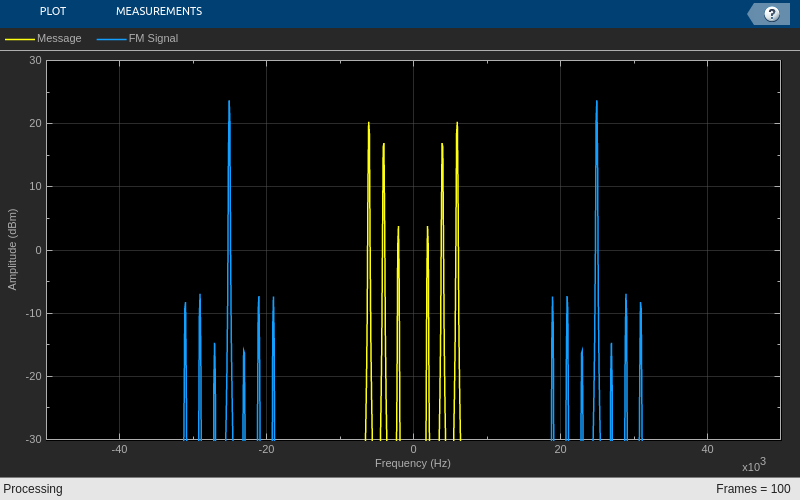

clc; clear; close all;

FrameSize = 1011;                % размер обрабатываемой за один раз пачки данных
Fs = 100e3;                      % частота дискретизации (Hz)
Fc = 25e3;                       % частота несущей (Hz)
Am = [0.1 0.5 0.7];              % амплитуды тональнов сообщения
Fm = [2e3 4e3 6e3];              % частоты тональнов сообщения (Hz)
ModIndex = 0.1;   % индекс модуляции

% вычисление чувствительности модулятора
Kf = ModIndex * Fm(end) / sum(Am);

% генератор сообщения из трех тонов
Message = dsp.SineWave(...
    'SampleRate', Fs, ...
    'SamplesPerFrame', FrameSize, ...
    'Frequency', Fm, ...
    'Amplitude', Am ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm', ...
    'FrequencyRange', 'centered', ...
    'SampleRate', Fs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -Fs/2, ...
    'YLimits', [-30, 30], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'FM Signal'}, ...
    'SampleIncrement', Fs/FrameSize ...
    );

% начальная фаза интегратора
InitPhase = 0;

% запуск симуляции
for i = 1:100
    % формирование сообщения из нескольких тонов
    MessageData = Message();
    MessageData = MessageData(:,1) + MessageData(:,2) + MessageData(:,3);

    % вычисление мгновенной частоты (Hz)
    freq = Fc + Kf * MessageData;
    
    % вычисление фазы в радианах c помощью интегрирования
    phase = InitPhase + 2*pi/Fs * cumsum(freq);
    
    % обновление начальной фазы интегратора
    InitPhase = phase(end);
    
    % формирование модулированного сигнала
    FmSignal = cos(phase);
    
    % вычисление спектров
    Spectrums = SpecEstimator([MessageData, FmSignal]);
    
    % вывод результатов на график
    Plotter(Spectrums)
    
    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.1)
end

Как и в предыдущем примере, при малом значении индекса модуляции $\beta$ спектр похож на спектр АМ-сигнала и из тона на несущей частоте и двух боковых полос. При увиличении индекса модуляции $\beta$ в спектре появляется множетсво гармоник и его ширина существенно возрастает. 

### 4. Модуляция аудиосигналом

Рассмотрим, как будет выглядеть спектр сигнала после модуляции, если информационное сообщение является аудиосигналом. В файле Audio_Source.wav записано звуковое сообщение с частотой дискретизации $f_s =44\ldotp 1$ kHz. Частота несущей будет равна 100 kHz. Чтобы избежать наложения спектров, выберем итоговую частоту дискретизации модулированного сигнала в 10 раз больше частоты аудиосигнала, то есть 10 * 44.1 kHz. Это потребует провести интерполяцию для увеличения частоты дискретизации информационного сообщения.

Максимальное значение отсчетов данного конкретного аудиосигнала равно единице, то есть $\max \left|m\left(t\right)\right|=1\ldotp$ Также будем считать, что максимальная частота в спектре сообшения равна половине частоты дискретизации:

$f_m =\frac{f_s }{2}=22\ldotp 05\;\textrm{kHz}$.

Отсуда, индекс модуляции можно записать в виде:

 
$$\beta =\frac{K_f \cdot \max \left|m\left(t\right)\right|}{f_m }=2\cdot \frac{K_f }{f_s },$$


где $N$- число гармоник. 

Тогда чувствиельность модулятора можно представить в виде:

 
$$K_f =\frac{\beta \cdot f_s }{2}\ldotp$$


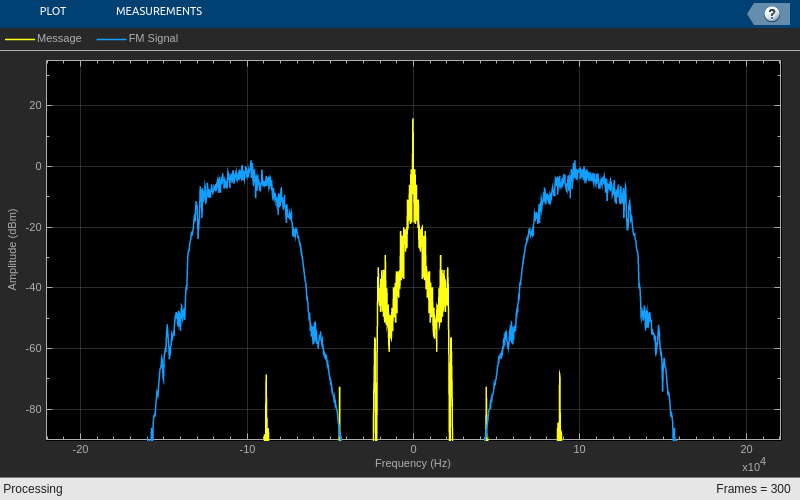

clc; clear; close all;

AudioFrameSize = 1000;           % количество отсчетов аудиофайла, получаемых за один раз
FramesNumber = 300;              % число обрабатываемых пачек данных
RateRatio = 10;                  % коэффициент увеличения частоты дискретизации
Fc = 100e3;                      % частота несущей (Hz)
ModIndex = 1.5;   % индекс модуляции

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_Source.wav', ...
    'SamplesPerFrame',AudioFrameSize...
    );

% дополнительные расчеты
AudioFs = AudioReader.SampleRate;               % получаем частоту дискретизации аудиосообщения
SignalFs = AudioFs * RateRatio;                 % частота дискретизации модулированного сигнала
SignalFrameSize = AudioFrameSize * RateRatio;   % количество отсчетов Ам-сигнала, получаемых за один раз

% вычисление чувствительности модулятора
Kf = ModIndex * AudioFs / 2;

% интерполятор 
Upsampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate',AudioFs, ...
    'OutputSampleRate', SignalFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'FM Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

% начальная фаза интегратора
InitPhase = 0;

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов аудиосообщения и выделение одного канала из
    % стерео сигнала
    AudioData = AudioReader();
    AudioData = AudioData(:,1);
    
    % увеличение частоты дискретизации аудиосообщения
    MessageData = Upsampler(AudioData);

    % вычисление мгновенной частоты (Hz)
    freq = Fc + Kf * MessageData;
    
    % вычисление фазы в радианах c помощью интегрирования
    phase = InitPhase + 2*pi/SignalFs * cumsum(freq);
    
    % обновление начальной фазы интегратора
    InitPhase = phase(end);
    
    % формирование модулированного сигнала
    FmSignal = cos(phase);

    % вычисление спектров
    SpectrumData = SpecEstimator([MessageData, FmSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.05)
end

Можно увидеть, что при увеличении индекса модуляции ширина спектра увеличивается, и он становится все менее похожим на спектр информационного сообщения.

### 5. Готовые решения Matlab

В среде Matlab есть готовая функция для выполнения частотной модуляции: fmmod(). Проверим ее работу. Функция принимает на вход информационный сигнал, частоту несущей, частоту дискретизации, девиацию и начальную фазу несущей. 

С учетом рассуждений из предыдущего параграфа девиацию можно выразить следующим образом:


$$\Delta f=K_f \cdot \max \left|m\left(t\right)\right|=K_f \cdot 1=K_f \ldotp$$


Основная часть скрипта совпадает со скриптом из предыдущего раздела.

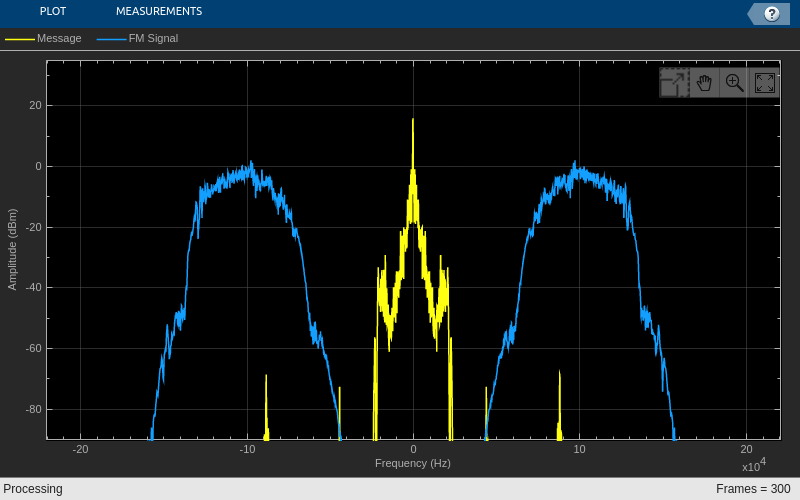

clc; clear; close all;

AudioFrameSize = 1000;          % количество отсчетов аудиофайла, получаемых за один раз
FramesNumber = 300;             % число обрабатываемых пачек данных
RateRatio = 10;                 % коэффициент увеличения частоты дискретизации
Fc = 100e3;                     % частота несущей (Hz)
ModIndex = 1.5;  % индекс модуляции

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_Source.wav', ...
    'SamplesPerFrame',AudioFrameSize...
    );

% дополнительные расчеты
AudioFs = AudioReader.SampleRate;               % получаем частоту дискретизации аудиосообщения
SignalFs = AudioFs * RateRatio;                 % частота дискретизации модулированного сигнала
SignalFrameSize = AudioFrameSize * RateRatio;   % количество отсчетов Ам-сигнала, получаемых за один раз

% вычисление чувствительности модулятора и девиации
Kf = ModIndex * AudioFs / 2;
FreqDeviation = Kf;

% интерполятор 
Upsampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate',AudioFs, ...
    'OutputSampleRate', SignalFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Message', 'FM Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

% начальная фаза интегратора
InitPhase = 0;

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов аудиосообщения и выделение одного канала из
    % стерео сигнала
    AudioData = AudioReader();
    AudioData = AudioData(:,1);
    
    % увеличение частоты дискретизации аудиосообщения
    MessageData = Upsampler(AudioData);

    % частотная модуляция аудиосообщения
    FmSignal = fmmod(MessageData, Fc, SignalFs, FreqDeviation, InitPhase);
    
    % обновление начальной фазы в радианах несущей после модуляции
    phase = InitPhase + 2*pi/SignalFs * cumsum(Fc + Kf * MessageData);
    InitPhase = phase(end);
   
    % вычисление спектров
    SpectrumData = SpecEstimator([MessageData, FmSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.05)
end

Спектр модулированного сигнала совпадает со спектром из предыдущего пункта.

### 6. Simulink модель

В файле FM_Transmitter_Basics.slx представлена Simulink-модель модуляции аудиосообщением. Как и в предыдущих скриптах в файле Audio_Source.wav записано звуковое сообщение с частотой дискретизации 44.1 kHz. Частота несущей равна 100 kHz. Перед модуляцией частота дискретизации увеличивается в 100 раз. Блок FM принимает и выдает данные только по одному отсчету. Поэтому до этого блока данные преобразуются из вектора в отсчеты (Unbuffer), а после него опять собираются в вектор (Buffer). С помощью слайдера можно изменить значение девиации и увидеть ее влияние на спектр сигнала. Схема модели и спектры сигналов представлены ниже:

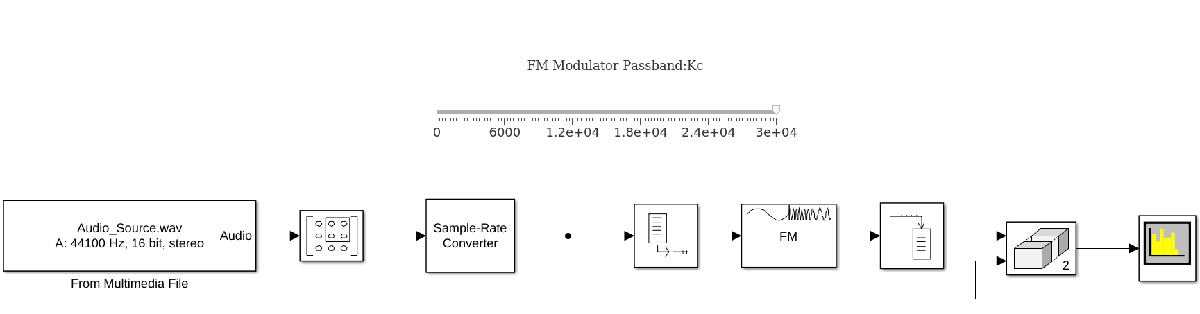

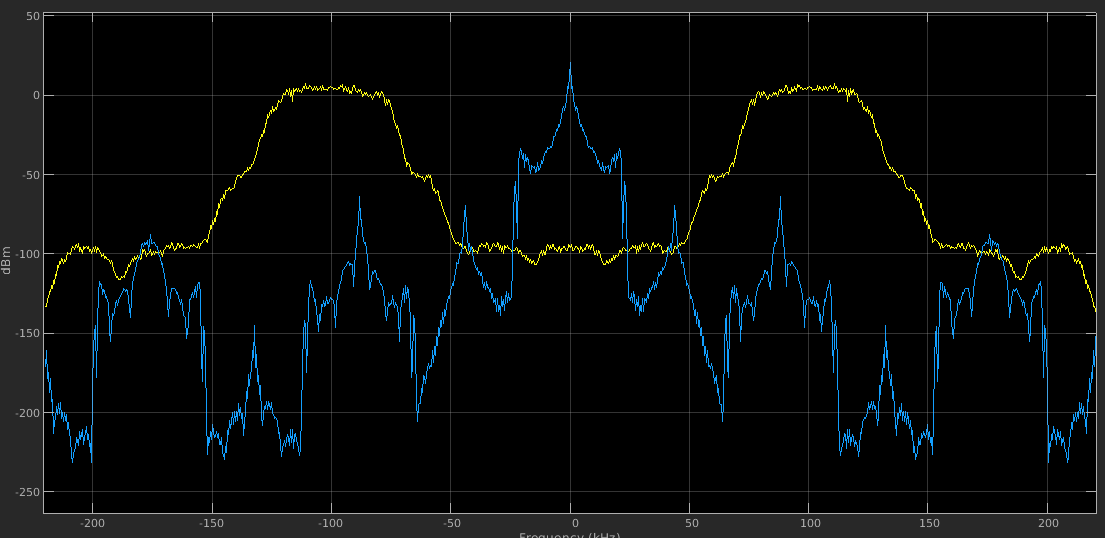

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR